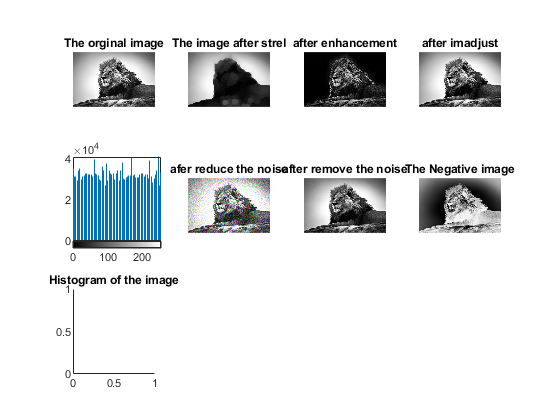

% Image enhancement 
clc; close all;
I = imread('lion.jpg');
subplot(3,4,1);
imshow(I);
title('The orginal image');
%-----------------------------------
se = strel('disk',30);
Background = imopen(I,se);
subplot(3,4,2);
imshow(Background);
title("The image after strel");
%---------------------------------------
enhanceImage=I-Background;
subplot(3,4,3);
imshow(enhanceImage);
title("after enhancement");
%-----------------------------------------
J=imadjustn(I);
subplot(3,4,4);
imshow(J);
title("after imadjust");
%----------------------------------------
h=histeq(I);
subplot(3,4,5);
imhist(h);
subplot(3,4,9);
title("Histogram of the image");
%------------------------------------------
IJ=imnoise(I,'gaussian',0.1);
subplot(3,4,6);
imshow(IJ);
title("afer reduce the noise");
%-----------------------------------------
r=medfilt3(h);
subplot(3,4,7);
imshow(r);
title("after remove the noise");
%----------------------------------------------
N=255-I;
subplot(3,4,8);
imshow(N);
title("The Negative image");